% Change the directory as you wish
clear;
clc;

% Faren root
% addpath 'D:\University\IEEE SP Cup\Share';
% root = 'D:\University\IEEE SP Cup\spcup_2022_training_part1';

% Alol root
addpath 'C:\Users\alisa\OneDrive\Documents\GitHub\SP-Cup-2022\Matlab_Script_Piazza'
root = 'C:\Users\alisa\OneDrive\Desktop\SP Cup\Dataset\spcup_2022_training_part1';

% addpath 'I:\Ashkan\SP_CUP_2022\Share';
% root = 'I:\Ashkan\SP_CUP_2022\spcup_2022_training_part1';

ads = getSPCup2022Datastore(root);

ads_shuffled = shuffle(ads);
fs = 16000;

numPartitions = 10;
iter = 1;
numSamples = zeros();
max_len_out = [];
parfor ii = 1:numPartitions
    max_len = 0;
    subads = partition(ads,numPartitions,ii);
    while hasdata(subads)
        [data,info] = read(subads);        
        x = data{1}
        s = size(x,1);
        if(s > max_len)
            max_len = s;
        end
    end
    max_len_out = [max_len_out, max_len]
end
max_len_in_dataset = max(max_len_out);

% max_len_in_dataset = 236287;
WindowLength = 512;
OverlapLength = 384;

numPartitions = 10;
tic
TrainingFeatures = {};
TrainingLabels= {};
parfor ii = 1:numPartitions
    
    subads = partition(ads,numPartitions,ii);
       
    count = 1;
    numLocalFiles = length(subads.UnderlyingDatastores{1}.Files)
    localFeatures = cell(numLocalFiles,1);
    localLabels = cell(numLocalFiles,1);
    
    while hasdata(subads)
        segmentSamples = max_len_in_dataset;
        % Create a training sentence
        [data,info] = read(subads);

        % zero pad
        x = data{1};
        numSamples = size(x,1);
        numToPadFront = floor( (segmentSamples - numSamples)/2 );
        numToPadBack = ceil( (segmentSamples - numSamples)/2 );
        xpadded = [zeros(numToPadFront,1,'like',x);x;zeros(numToPadBack,1,'like',x)];
        
        lab = data{2};
        fs = info{1}.SampleRate;
        
        % Compute features
        ee = 1
        featureMatrix = abs(spectrogram(xpadded,WindowLength,OverlapLength,32));
        featureMatrix(~isfinite(featureMatrix)) = 0;
        ee = 2

        % Create label array with matching depth
        labels = repmat(lab,[size(featureMatrix,1),1]);

        localFeatures{count} = featureMatrix;
        localLabels{count} = labels;
        
        count = count + 1;
    end
    
    TrainingFeatures = [TrainingFeatures;localFeatures];
    TrainingLabels = [TrainingLabels;localLabels];
end

sampleFeature = TrainingFeatures{1};
numFeatures = size(sampleFeature,2);
featuresMatrix = cat(1,TrainingFeatures{:});
M = mean(featuresMatrix);
S = std(featuresMatrix);
for index = 1:length(TrainingFeatures)
    f = TrainingFeatures{index};
    f = (f - M) ./ S;
    TrainingFeatures{index} = f; %#ok
end

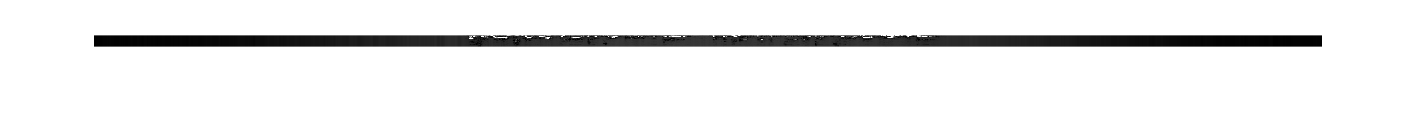

% imshow(abs(TrainingFeatures{1}))

data_len = length(TrainingLabels);
shuffled_idxs = randperm(data_len);
ShuffledTrainingFeatures = TrainingFeatures(shuffled_idxs);
ShuffledTrainingLabels = TrainingLabels(shuffled_idxs);

% Change directories as you wish
TrainFeatures = ShuffledTrainingFeatures;
TrainLabels = ShuffledTrainingLabels;

TrainLabelsArray = zeros([length(TrainFeatures),1]);
for i = 1:length(TrainFeatures)
%     Alol root
    dest = "C:\Users\alisa\OneDrive\Desktop\SP Cup\Network-inputs\Train-Data\";
%     main root
%     dest = 'I:\Ashkan\SP_CUP_2022\Network-inputs\Train-Data\';
%     Faren root
%     dest = 'D:\University\IEEE SP Cup\Network-inputs\Train-Data\';

    img_name = dest+string(i)+'.png';
    imwrite(TrainFeatures{i},img_name);

    TrainLabelsArray(i) = double(TrainLabels{i}(1))-1;
end

writematrix(TrainLabelsArray, string(dest)+'Train-Labels');

dest = "C:\Users\alisa\OneDrive\Desktop\SP Cup\Network-inputs\Train-Data\";
for i=1:6000
    switch TrainLabelsArray(i)
        case 1
            copyfile(dest+string(i)+'.png',dest+'1\'+string(i)+'.png') 
        case 2
            copyfile(dest+string(i)+'.png',dest+'2\'+string(i)+'.png')
        case 3/
            copyfile(dest+string(i)+'.png',dest+'3\'+string(i)+'.png')
        case 4
            copyfile(dest+string(i)+'.png',dest+'4\'+string(i)+'.png')
        case 5
            copyfile(dest+string(i)+'.png',dest+'5\'+string(i)+'.png')
        case 0
            copyfile(dest+string(i)+'.png',dest+'0\'+string(i)+'.png')
    end
end